# Hailing Ileum segmentation test

## 2D

base_path = fullfile("D:/2021-01-17-Hailing-Ileum/output/segmentation/");
dapi = imread(fullfile(base_path, "Section7-0030-dapi.tif"));
protein = imread(fullfile(base_path, "Section7-0030-protein.tif"));

figure
imshowpair(dapi, protein)

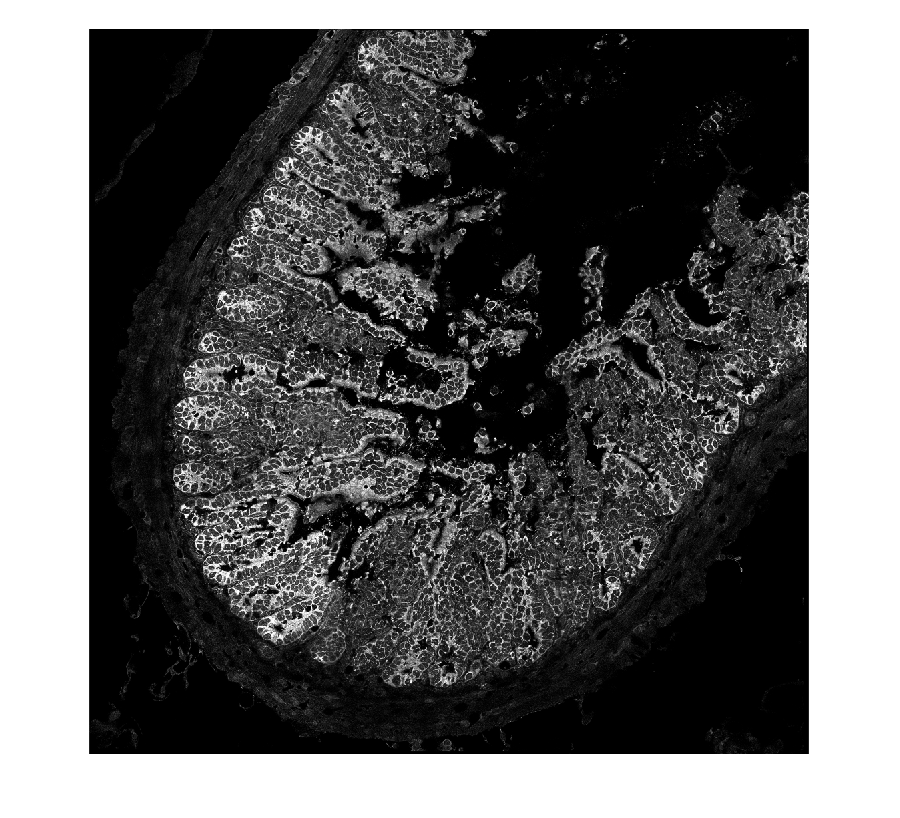

protein_thres = imadjust(protein);
protein_thres = imgaussfilt(protein_thres, 2);
protein_mask = protein_thres > 100;
% protein_mask = imbinarize(protein_thres);
se = strel('disk', 5);
se2 = strel('disk', 10);
protein_mask = bwareaopen(protein_mask, 500);
protein_mask = imclose(protein_mask, se);
protein_mask_2 = imclose(protein_mask, se2);

figure
imshow(protein_thres)

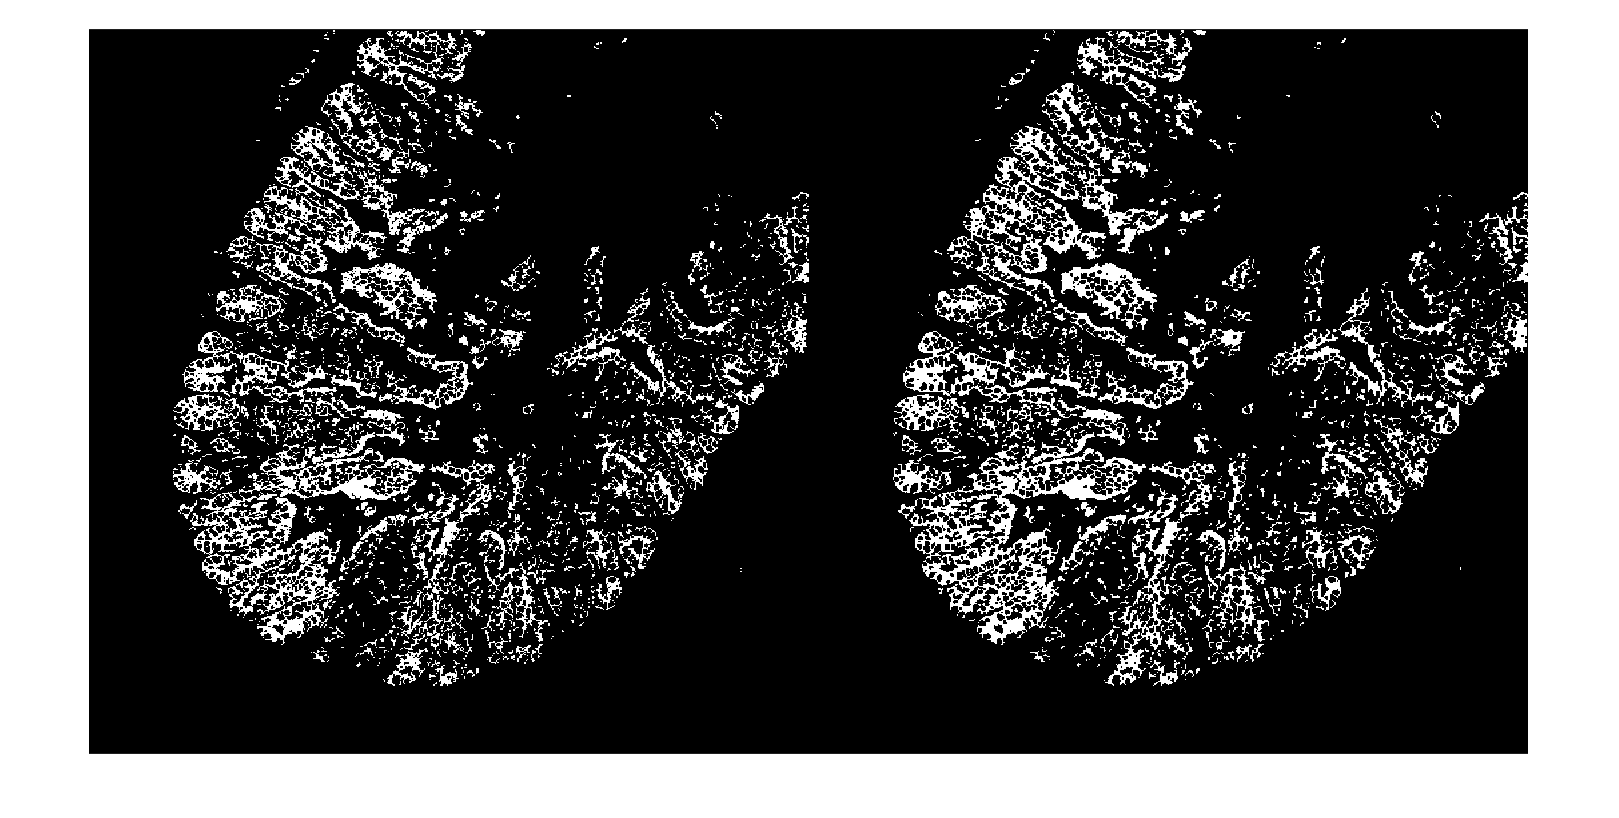


% figure
% imshow(protein_mask)

figure
imshowpair(protein_mask, protein_mask_2, 'montage')

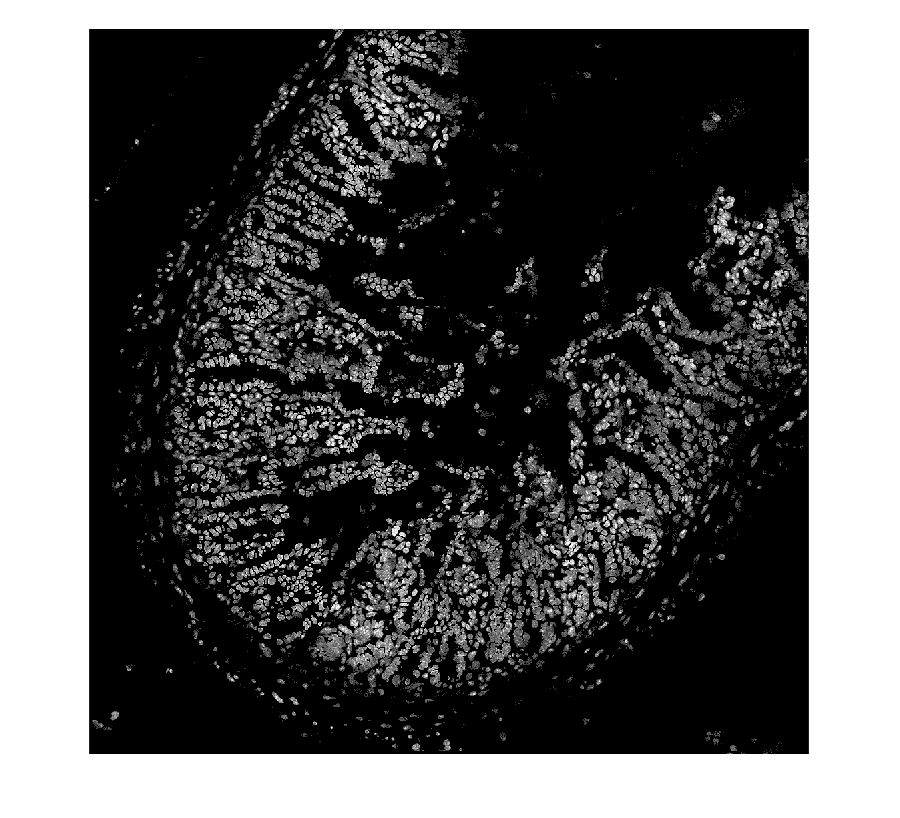


dapi_filtered = imadjust(dapi);
dapi_filtered = imgaussfilt(dapi_filtered, 2);
dapi_filtered(protein_mask_2) = 0; 
dapi_filtered(dapi_filtered < 50) = 0;

figure
imshow(dapi_filtered)


imwrite(dapi_filtered, fullfile(base_path, 'output/section7_test.tif'))

dapi_bw = imbinarize(dapi_filtered);
dapi_bw = bwareaopen(dapi_bw, 50);
dapi_bw = imfill(dapi_bw, 'holes');
se = strel('disk', 2);
dapi_bw = imdilate(dapi_bw, se);
figure
imshow(dapi_bw)

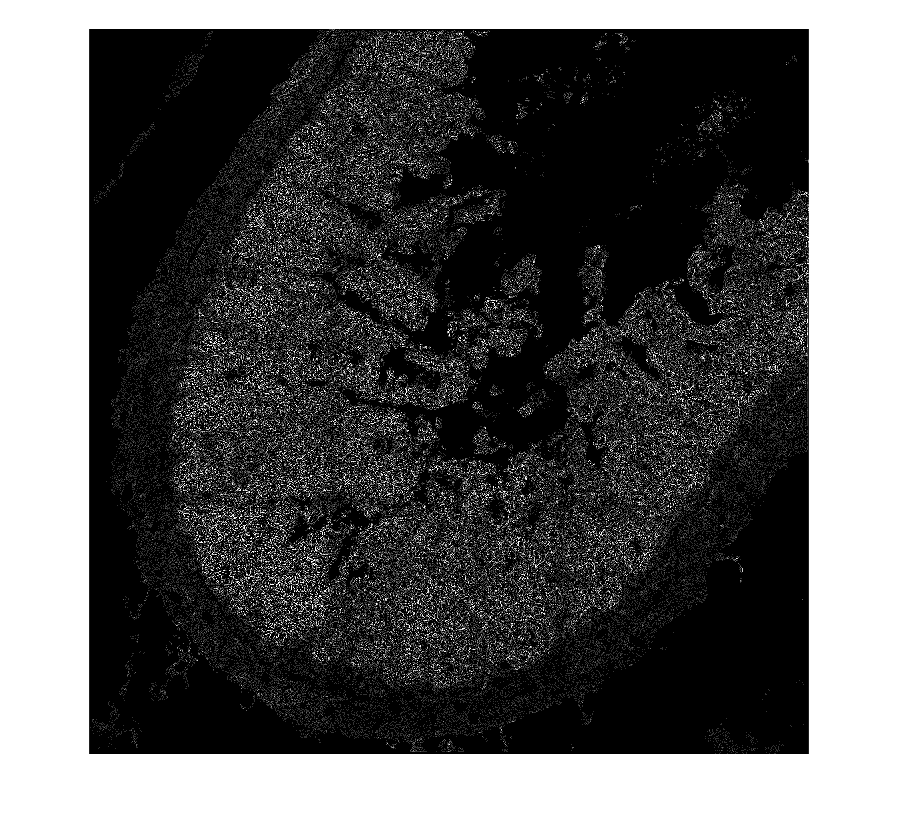

h = fspecial('log', [100 100], 2);
protein_bulb = imfilter(protein_thres, h);
protein_bulb = imadjust(protein_bulb);
figure
imshow(protein_bulb)

imwrite(protein_bulb, fullfile(base_path, 'output/section7_log.tif'))

## 3D